# Hellinger-Reissner Formulation for the Timoshenko Beam Boundary Value Problem - A Study

## Introduction

This chapter performs a similar study as Live Script [`main_Chapter4_TransverseShearLocking_TimoshenkoBeam.mlx`](matlab:open('..\4_TransverseShearLocking\4_TransverseShearLocking_TimoshenkoBeam\main_Chapter4_TransverseShearLocking_TimoshenkoBeam.mlx')) by also adding the Hellinger-Reissner formulation in the studies regarding the transverse-shear locking. As in Live Script [`main_Chapter4_TransverseShearLocking_TimoshenkoBeam.mlx`](matlab:open('..\4_TransverseShearLocking\4_TransverseShearLocking_TimoshenkoBeam\main_Chapter4_TransverseShearLocking_TimoshenkoBeam.mlx')), the transverse-shear locking that is exhibited by the low-order Finite Element discretizations of the [Timoshenko beam theory](https://en.wikipedia.org/wiki/Timoshenko%E2%80%93Ehrenfest_beam_theory) for the setup of a cantilever beam subject to vertical distributed load $\overline{q}$, see the following figure:

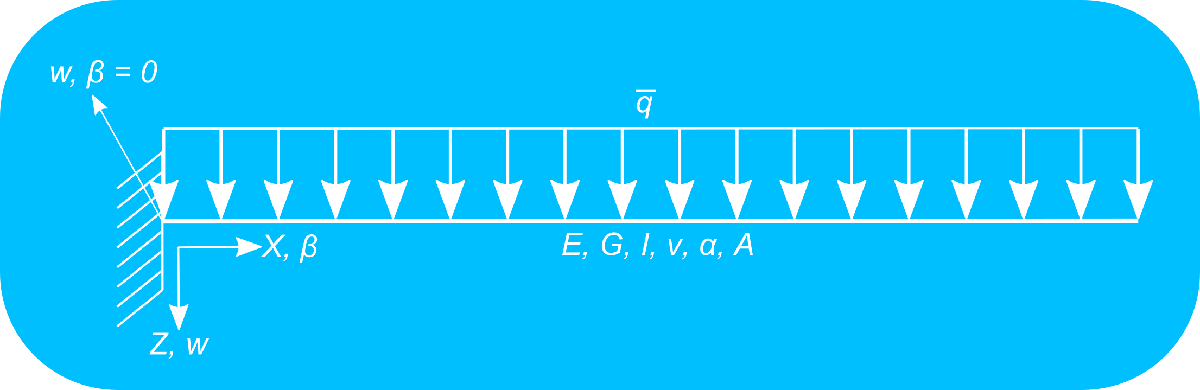

For this problem setup there is an analytical solution both in terms of the vertical deflection and the cross-sectional rotation, see the corresponding [derivation](matlab:open('..\1_TimoshenkoBeam\main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx')) at the Live Script [`main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx`](matlab:open('..\1_TimoshenkoBeam\main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx')) for more information.

[PREVIOUS Chapter](matlab:open('./main_Chapter6_HellingerReissnerFormulation_TimoshenkoBeam.mlx')) *Hellinger-Reissner Formulation for the Timoshenko Beam Boundary Value Problem*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;

## **Problem parameters**

### Geometric parameters

Thickness [m]

propStr.t = 10^(-1);

Width [m]

propStr.b = 1;

Height [m^2]

propStr.A = propStr.b*propStr.t;

X-coordinate at the left end of the beam [m]

X0 = 0;

Y-coordinate at the right end of the beam [m]

XL = 4;

### Material paramerters

Distributed load along the beam's length [N/m^2]

propStr.qBar = -1e1*propStr.t;

Distributed moment along the beam's length [N/m]

propStr.mBar = 0;

Boundary force [N]

propStr.Q = 0;

Boundary moment [Nm]

propStr.M = 0;

Young's modulus [N/m^2]

propStr.E = 1e7;

Poisson ratio [dimensionless]

propStr.nu = 0.3;

Moment of inertia [m^4]

propStr.I = propStr.b*(propStr.t^3)/12;

Shear modulus (connected to epsilon_12 = E/(1+nu)) [N/m^2]

propStr.G = propStr.E/(2*(1 + propStr.nu));

Shear correction factor [dimensionless]

propStr.alpha = 5/6;

## Analytical solution

### Initialization of auxiliary variables

syms wEx(X) betaEx(X) QEx(X) Lsym qsym Gsym Acs alphaScf Aqsym Esym Isym

### Analytical solution with respect to the vertical deflection

wEx(X) = (qsym*Lsym*X-qsym*X^2/2)/Gsym/(Aqsym) - ...
    (-qsym*X^4/24+qsym*Lsym*X^3/6-qsym*Lsym^2*X^2/4)/Esym/Isym;

### Analytical solution with respect to the cross-sectional rotation

Get the analytical solution of the rotational field by leveraging the Partial Differential Equation (PDE) of the problem and the functions of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)®


$$\beta(X) = \int_{0}^L - \frac{1}{\alpha G A}\overline{Q} - \frac{\text{d}^2 w}{\text{d} x^2} \: \text{d}x \quad \quad (1)$$


betaEx(X) = int(-1/(propStr.alpha*propStr.G*propStr.A)*propStr.qBar ...
    - diff(diff(wEx, X), X));

### Evaluation of the expressions for the given geometric and material parameters

QEx(X) = alphaScf*Gsym*Acs*(diff(wEx(X), X, 1) + betaEx(X));

### Evaluation of the expressions for the given geometric and material parameters

wEx(X) = subs(wEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});
betaEx(X) = subs(betaEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});
QEx(X) = subs(QEx, {alphaScf, Gsym, Acs, Lsym, qsym, Gsym, Esym, ...
    Isym, Aqsym}, {propStr.alpha, propStr.G, propStr.A,XL, propStr.qBar, ...
    propStr.G, propStr.E, propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});

## Analytical expressions for the one-dimensional basis functions

### Analytical expressions for the linear basis functions

syms N1L1(xi) N2L1(xi)
N1L1(xi) = (1 - xi)/2;
N2L1(xi) = (1 + xi)/2;
NL1 = [N1L1 N2L1];

### Analytical expressions for the quadratic basis functions

syms N1L2(xi) N2L2(xi) N3L2(xi)
N1L2(xi) = (xi*(xi - 1))/2;
N2L2(xi) = (xi*(xi + 1))/2;
N3L2(xi) = 1 - xi^2;
NL2 = [N1L2 N2L2 N3L2];

## **Discretization**

The vertical deflection and rotation fields are discretized using the shape shape functions $N_i^u \;\left(\xi \right)$. Similarly, both the reaction transverse-shear forces and reaction bending moments are discretized using the same shape functions $N_i^{\beta } \;\left(\xi \right)$. Note, that the shape function sets $N_i^u \;\left(\xi \right)$ and $N_i^{\beta } \;\left(\xi \right)$ do not have to be the same.


$$\begin{array}{l}
w\left(\xi \right)\approx \sum_{i=1:N} N_i^u \;w_i ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\ldotp 1\right)\\
\beta \left(\xi \right)\approx \sum_{i=1:N} N_i^u \;\beta_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\ldotp 2\right)\\
Q\left(\xi \right)\approx \sum_{i=1:N} N_i^{\beta } \;Q_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 3\right)\\
M\left(\xi \right)\approx \sum_{i=1:N} N_i^{\beta } \;M_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\ldotp 4\right)
\end{array}$$


### One-dimensional linear two-noded mesh

#### Mesh generation

numElL1 = 9;
mshL1 = generateLinearMeshOnLine(X0, XL, numElL1);
numNodesL1 = numel(mshL1.nodes);

#### Dirichlet boundary conditions

freeDOFsL1 = 1:2*numNodesL1;
numDOFsL1 = 2*numNodesL1;
homDOFsL1 = 1:2;
[~, idxL1] = ismember(homDOFsL1, freeDOFsL1);
freeDOFsL1(idxL1) = [];

#### Mesh plot

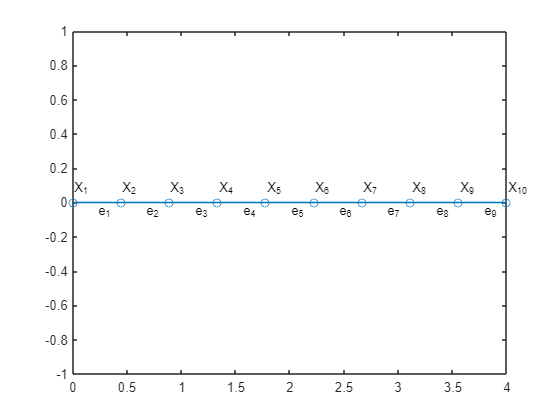

figure,
title("Finite Element discretization of the beam")
plotMesh1d(mshL1);

### One-dimensional quadratic three-noded mesh

#### Mesh generation

mshL2 = generateQuadraticMeshOnLine(mshL1);
numNodesL2 = numel(mshL2.nodes);

#### Dirichlet boundary conditions

freeDOFsL2 = 1:2*numNodesL2;
numDOFsL2 = 2*numNodesL2;
homDOFsL2 = 1:2;
[~, idxL2] = ismember(homDOFsL2, freeDOFsL2);
freeDOFsL2(idxL2) = [];

#### Mesh plot

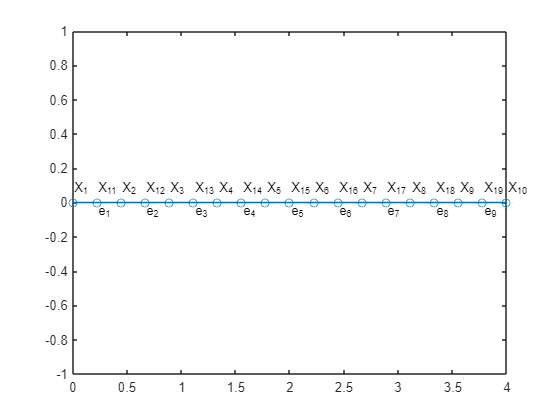

plotMesh1d(mshL2)

## **Master stiffness matrices and master consistent nodal force vectors for the standard Timoshenko beam Finite Element formulations**

### Linear finite elements and full integration

#### Master stiffness matrix and load vector

computeStiffMatrixandForceVectorTB = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
computeBasisFunctionsAndDerivsU = ...
    @computeLinearBasisFunctionsAndFirstDerivatives;
computeBasisFunctionsAndDerivsBeta = 'undefined';
[KL1, FL1Body] = ...
    computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL1, computeStiffMatrixandForceVectorTB, ...
    computeBasisFunctionsAndDerivsU, computeBasisFunctionsAndDerivsBeta, ...
    propStr);

#### Nodal force vector corresponding to boundary forces

FL1Boundary = zeros(2*numNodesL1, 1);
FL1Boundary(end - 1, 1) = propStr.Q;
FL1Boundary(end, 1) = propStr.M;

#### Sum-up of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL1 = FL1Body + FL1Boundary;

#### Sparsity pattern of the master stiffness matrix using linear finite elements corresponding to the full integration

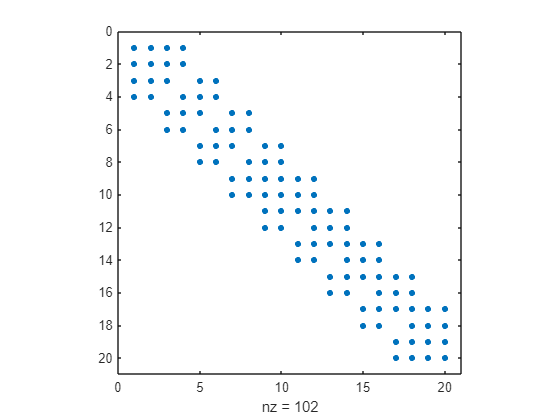

spy(KL1)

### Linear finite elements and selective-reduced integration

#### Master stiffness matrix and load vector

computeStiffMatrixandForceVectorTB = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeamRI;
computeBasisFunctionsAndDerivsU = ...
    @computeLinearBasisFunctionsAndFirstDerivatives;
computeBasisFunctionsAndDerivsBeta = 'undefined';
[KL1RI, FBodyL1RI] = ...
    computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL1, computeStiffMatrixandForceVectorTB, ...
    computeBasisFunctionsAndDerivsU, computeBasisFunctionsAndDerivsBeta, ...
    propStr);

#### Nodal force vector corresponding to boundary forces

FL1BoundaryRI = zeros(2*numNodesL1, 1);
FL1BoundaryRI(end - 1, 1) = propStr.Q;
FL1BoundaryRI(end, 1) = propStr.M;

#### Sum-up the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL1RI = FBodyL1RI + FL1BoundaryRI;

#### Sparsity pattern of the master stiffness matrix using linear finite elements corresponding to the full integration

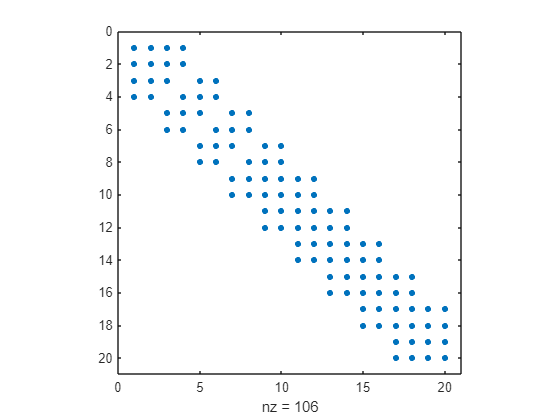

spy(KL1RI)

### Quadratic finite elements and full integration

#### Master stiffness matrix and load vector

computeStiffMatrixandForceVectorTB = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
computeBasisFunctionsAndDerivsU = ...
    @computeQuadraticBasisFunctionsAndFirstDerivatives;
computeBasisFunctionsAndDerivsBeta = 'undefined';
[KL2, FBodyL2] = ...
    computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL2, computeStiffMatrixandForceVectorTB, ...
    computeBasisFunctionsAndDerivsU, computeBasisFunctionsAndDerivsBeta, ...
    propStr);

#### Nodal force vector corresponding to boundary forces

FBoundaryL2 = zeros(2*numNodesL2, 1);
FBoundaryL2(2*numNodesL1 - 1, 1) = propStr.Q;
FBoundaryL2(2*numNodesL1, 1) = propStr.M;

#### Sum-up the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL2 = FBodyL2 + FBoundaryL2;

#### Sparsity pattern of the master stiffness matrix using linear finite elements corresponding to the full integration

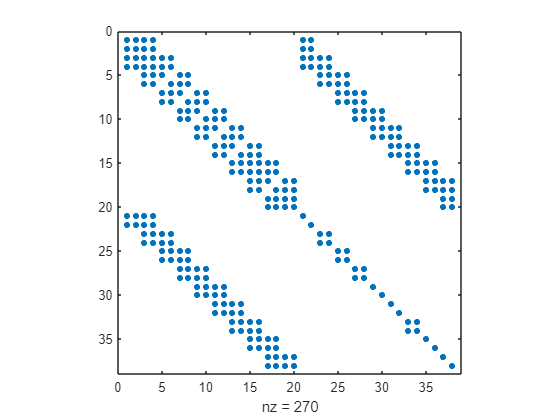

spy(KL2)

## **Master stiffness matrices and master consistent nodal force vectors for the standard Euler-Bernoulli beam Finite Element formulation**

For this standard Euler-Bernoulli beam Finite Element formulation it is used the discretization of the 4th order PDE by means of the [cubic Hermite polynomials](https://en.wikipedia.org/wiki/Cubic_Hermite_spline).

### Master stiffness matrix and load vector

propStrEB = propStr;
propStrEB.q = propStr.qBar;
propStrEB.m = propStr.mBar;
computeStiffMatrixandForceVectorEBT = ...
    @computeElementStiffMatrixandForceVectorEulerBernoulliBeam;
[KEB, FBodyEB] = ...
    computeMasterStiffMatrixandForceVectorEulerBernoulliBeam ...
    (mshL1, computeStiffMatrixandForceVectorEBT, propStrEB);

### **Nodal force vector corresponding to boundary forces**

FBoundaryEB = zeros(2*numNodesL1, 1);
FBoundaryEB(end - 1, 1) = propStr.Q;
FBoundaryEB(end, 1) = - propStr.M;

### Sum-up of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FEB = FBodyEB + FBoundaryEB;

### Sparsity pattern of the master stiffness matrix using linear finite elements corresponding to the full integration

spy(KEB)

## Master stiffness matrices and master consistent nodal force vectors for the Timoshenko beam Finite Element formulation using the Hellinger-Reissner principle

### **Master stiffness matrix and load vector using the Hellinger-Reissner principle**

computeStiffMatrixandForceVectorHR = ...
    @computeElStiffMtxForceVctHellingerReissnerTimoshenkoBeam;
choiceShapeFunctionsU = 1;
choiceShapeFunctionsLM = 0;
switch choiceShapeFunctionsU
    case 1
        numDOFsHR = numDOFsL1;
        computeBasisFunctionsAndDerivsHRU = ...
            @computeLinearBasisFunctionsAndFirstDerivatives;
        freeDOFsHR = freeDOFsL1;
        mshHR = mshL1;
    case 2
        numDOFsHR = numDOFsL2;
        computeBasisFunctionsAndDerivsHRU = ...
            @computeQuadraticBasisFunctionsAndFirstDerivatives;
        freeDOFsHR = freeDOFsL2;
        mshHR = mshL2;
    otherwise
        error("Variable 'choice_shapeFunctions_u' can only take values " + ...
            "1 (linear shape functions), 2 (quadratic shape functions) " + ...
            "but it has instead value %d", ...
        choiceShapeFunctionsU);
end
switch choiceShapeFunctionsLM
    case 0
        computeBasisFunctionsAndDerivsLM = ...
            @computeConstantBasisFunctionAndFirstDerivatives;
    case 1
        computeBasisFunctionsAndDerivsLM = ...
            @computeLinearBasisFunctionsAndFirstDerivatives;
    case 2
        computeBasisFunctionsAndDerivsLM = ...
            @computeQuadraticBasisFunctionsAndFirstDerivatives;
    otherwise
        error("Variable 'choice_shapeFunctions_LM' can only take values " + ...
            "0 (constant shape functions), 1 (linear shape functions) " + ...
            "or 2 (quadratic shape functions) but it has instead value %d", ...
            choiceShapeFunctionsLM);
end
[KHR, FBodyHR, invHGHR] = computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshHR, computeStiffMatrixandForceVectorHR, computeBasisFunctionsAndDerivsHRU, ...
    computeBasisFunctionsAndDerivsLM, propStr);

### **Nodal force vector corresponding to boundary forces**

FBoundaryL01HR = zeros(2*numNodesL1, 1);
FBoundaryL01HR(2*numNodesL1 - 1, 1) = propStr.Q;
FBoundaryL01HR(2*numNodesL1, 1) = propStr.M;

### Sum-up of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL01HR = FBodyHR + FBoundaryL01HR;

### Sparsity pattern of the master stiffness matrix using linear finite elements corresponding to the full integration

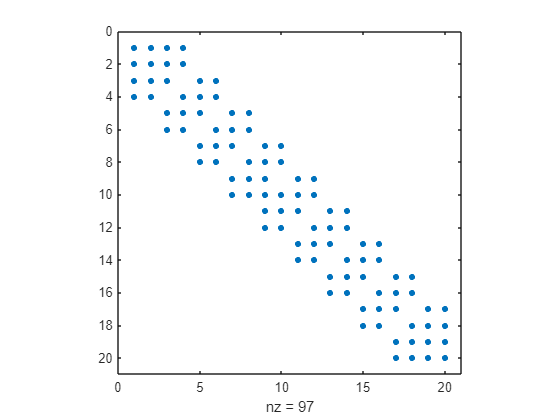

spy(KHR)

## Solution of the discrete standard Timoshenko beam Finite Element problem

### Linear finite elements and full integration

uL1 = zeros(numDOFsL1, 1);
uL1(freeDOFsL1, 1) = KL1(freeDOFsL1, freeDOFsL1)\FL1(freeDOFsL1);

### Linear finite elements and selective-reduced integration

uL1RI = zeros(numDOFsL1, 1);
uL1RI(freeDOFsL1, 1) = KL1RI(freeDOFsL1, freeDOFsL1)\FL1RI(freeDOFsL1);

### Quadratic finite elements and full integration

uL2 = zeros(numDOFsL2, 1);
uL2(freeDOFsL2, 1) = KL2(freeDOFsL2, freeDOFsL2)\FL2(freeDOFsL2);
[nodesL2, idx] = sort(mshL2.nodes);
wL2 = uL2(1:2:end, 1);
betaL2 = uL2(2:2:end, 1);

## Solution of the discrete Euler-Bernoulli beam problem

uEB = zeros(numDOFsL1, 1);
uEB(freeDOFsL1, 1) = KEB(freeDOFsL1, freeDOFsL1)\FEB(freeDOFsL1);

## Solution of the Timoshenko beam Finite Element formulation with the Hellinger-Reissner principle

### Solution of the linear equation system based on the pair of the primal unknowns

uL01HR = zeros(numDOFsL1, 1);
uL01HR(freeDOFsHR, 1) = KHR(freeDOFsHR, freeDOFsHR)\FL01HR(freeDOFsHR);

### Computation of the reaction transverse-shear forces along the beam by means of the pair of the secondary unknowns

betaL01HR = invHGHR*uL01HR;
QPtsL01HR = betaL01HR(1:2:end);

if numDOFsHR == numDOFsL1 && choiceShapeFunctionsLM == 0
    strHR = "L0-L1"
elseif numDOFsHR == numDOFsL1 && choiceShapeFunctionsLM == 1
    strHR = "L1-L1";
elseif numDOFsHR == numDOFsL1 && choiceShapeFunctionsLM == 2
    strHR = "L2-L1";
elseif numDOFsHR == numDOFsL2 && choiceShapeFunctionsLM == 0
    strHR = "L0-L2";
elseif numDOFsHR == numDOFsL2 && choiceShapeFunctionsLM == 1
    strHR = "L1-L2";
elseif numDOFsHR == numDOFsL2 && choiceShapeFunctionsLM == 2
    strHR = "L2-L2";
else
    error("This combination of basis functions for the primal and " + ...
        "secondary unknown fields is not supported")
end

strHR = "L0-L1"

## Postprocessing

### Deformed configuration

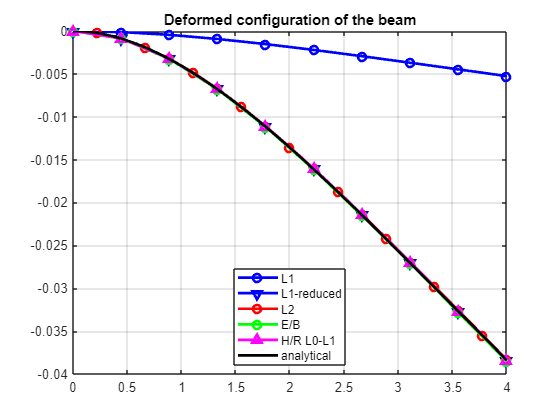

plot(mshL1.nodes, uL1(1:2:end, 1), '-bo', LineWidth=2);
hold on;
plot(mshL1.nodes, uL1RI(1:2:end, 1), '-bv', LineWidth=2);
plot(nodesL2, wL2(idx), '-ro', LineWidth=2);
plot(mshL1.nodes, uEB(1:2:end, 1), '-go', LineWidth=2);
plot(mshHR.nodes, uL01HR(1:2:end, 1), '-m^', LineWidth=2);
fplot(wEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
legend("L1", "L1-reduced", "L2", "E/B", "H/R " + strHR, "analytical", ...
    Location="best")
title("Deformed configuration of the beam")

### Cross-sectional rotation field

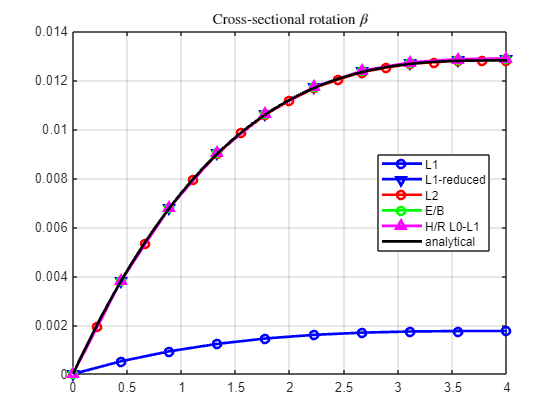

plot(mshL1.nodes, uL1(2:2:end, 1), '-bo', LineWidth=2);
hold on;
plot(mshL1.nodes, uL1RI(2:2:end, 1), '-bv', LineWidth=2);
plot(nodesL2, betaL2(idx), '-ro', LineWidth=2);
plot(mshL1.nodes, -uEB(2:2:end, 1), '-go', LineWidth=2);
plot(mshHR.nodes, uL01HR(2:2:end, 1), '-m^', LineWidth=2);
fplot(betaEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
legend("L1", "L1-reduced", "L2", "E/B", "H/R " + strHR, "analytical", ...
    Location="best")
title("Cross-sectional rotation $\beta$", Interpreter="latex")

## Transverse-shear locking due incompatible discretization spaces

The matter of transverse-shear locking and its presence in Finite Element formulation for shear-deformable structural elements is discussed in detail in Live Script [`main_Chapter3_Locking_Timoshenko_beam.mlx`](matlab:open('..\3_TransverseShearLocking\3_TransverseShearLocking_TimoshenkoBeam\main_Chapter3_TransverseShearLocking_TimoshenkoBeam.mlx')) at [this code section](matlab:open('..\3_TransverseShearLocking\3_TransverseShearLocking_TimoshenkoBeam\main_Chapter31_TimoshenkoBeamLocking_ShearForces.mlx')). As mentioned therein the issue is the incompatibility of the discretization spaces for the displacement and the cross-sectional rotation fields because of the use of the same basis functions for the discretization of both fields. If it is used linear shape functions then the transverse-shear deformation cannot represent zero-states by simply adding piecewise constant with piecewise linear functions, namely:


$$\gamma = \frac{\text{d}w}{\text{d}x} + \beta = \sum_{i=1}^n \overbrace{\frac{\text{d}N_i^w(\xi)}{\text{d}x}}^{\text{constant}} w_i + \sum_{i = 1}^n \overbrace{N_i^{\beta}(\xi)}^{\text{linear}} \beta_i \qquad (2)$$


This leads to the fact that residual spurious transverse-shear forces remain that eventually cause the transverse-shear locking numerical phenomenon. Another way to identify/explain transverse-shear locking is that the problem is overconstrained by means of the Kirchhoff constrain $\gamma \overbrace{=}^{!} 0$ in case of thin shear-deformable elements. A way to circumvent this issue to avoid in the first place having to incorporate this contrain in the variational form of the problem that describes the Partial Differential Equation (PDE) weakly. In the case of the Timoshenko beam one does not need to introduce the transverse-shear deformations into the variational form of the problem and leverage the inverse of the material law. The underlying derivation leads in this case to the following variational formulation leveraging the Hellinger-Reissner principle:


$$\int_0^L \delta \left( \frac{\text{d} w}{\text{d} x} + \beta \right) \, Q  \; \text{d} x - \delta Q \, \frac{1}{\alpha G A} \, Q + \delta Q \, \left( \frac{\text{d} w}{\text{d} x} + \beta \right) + \delta \frac{\text{d} \beta}{\text{d} x} \, M - \delta M \, \frac{1}{EI} \, M + \delta M \, \frac{\text{d} \beta}{\text{d} x} = \overbrace{\int_0^L \overline{q} \, \delta w + \overline{m} \, \delta \beta \; \text{d}x }^{\text{source loads}} + \overbrace{\left[ \delta w \, Q \right]_0^L + \left[ \delta \beta \, M \right]_0^L}^{\text{boundary loads}} \;. \quad (3)$$


The latter variational formulation is proven to be transverse-shear locking-free, however additional challenges are posed:

- The system involves additional unknowns (in this case the Lagrange Multipliers) which can be condensed out in particular situations

- The system is no longer necessarily positive definite meaning that the discretization spaces need to fullfil the [Ladyzenskaja-Babuska-Brezzi (LBB) (or alternative known as inf-sup) condition](https://en.wikipedia.org/wiki/Ladyzhenskaya%E2%80%93Babu%C5%A1ka%E2%80%93Brezzi_condition) so that a unique solution to the problem can be guaranteed

### Number of evaluation points for the transverse-shear forces

numPts = 50;

  **Try**

Modify the number of evaluation points by means of variable `numPts`

 **Reflect**

- How do the different distributions of the transverse-shear force change with respect to the number of evaluation points and why?

- How many evaluation points do you need to appropriately describe the different transverse-shear force distributions? Is this value constant or does it depend on the chosen value for the beam's length and thickness, $L$ and $t$, respectively?

### Transverse-shear force distribution along the beam's length

Navigate to [THIS](matlab:open('./main_Chapter61_HellingerReissnerTimoshenko_ShearForces.mlx')) section for the detailed analysis.

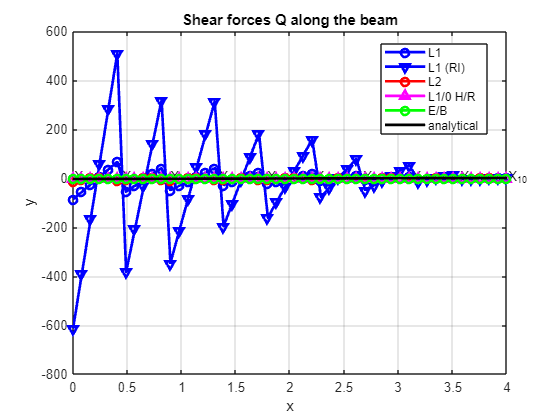

main_Chapter61_HellingerReissnerTimoshenko_ShearForces

## Convergence study on transverse shear-locking

In this section it is shown how the rate of the mesh convergence study is reduced down due to transverse shear locking. The effect gets more pronounced with increased slenderness of the beam.

### Number of elements

numEl = 100;
if floor(numEl) ~= numEl
    error("Variables 'numEl' must be an integer")
end
if numEl <= 0
    error("Variable 'numEl' must be strictly positive")
end

  **Try**

Modify the number of refinement steps by means of variable `numRef`

 **Reflect**

- Keep the slenderness of the beam small enough $\lambda = \frac{L}{t} \in \mathcal{O}(1)$. What is the critical number of elements beyond which no variation in the tip deflection of the beam is observed?

- Increase the slenderness of the beam to $\lambda \in \mathcal{O}(10^{-2})$. What is the critical number of elements beyond which no variation in the tip deflection of the beam is observed? Note that you may need to increase the number of refinements by means of variable `numRef` to observe convergence

### Convergence study based on the tip displacement of the beam

Navigate to [THIS](matlab:open('./main_Chapter62_HellingerReissnerTimoshenko_ConvergenceStudy.mlx')) section for the detailed analysis.

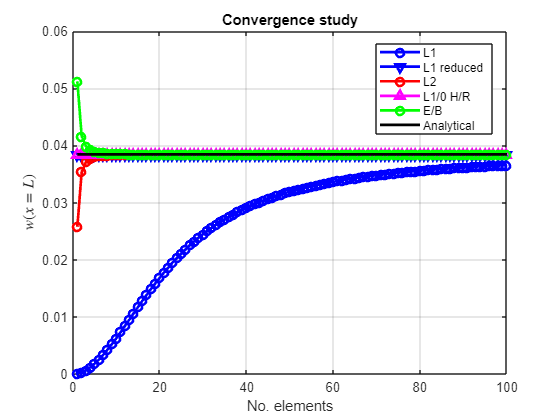

main_Chapter62_HellingerReissnerTimoshenko_ConvergenceStudy

## References

[[1] Koschnick, Frank. *Geometrische Locking-Effekte bei finiten Elementen und ein allgemeines Konzept zu ihrer Vermeidung*. Diss. München, Techn. Univ., Diss., 2004.](https://mediatum.ub.tum.de/doc/601060/0000003e.pdf)

[[2] Hughes, Thomas JR. *The finite element method: linear static and dynamic finite element analysis*. Courier Corporation, 2012.](https://doi.org/10.1111/j.1467-8667.1989.tb00025.x)